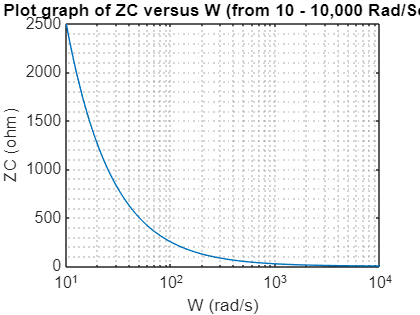

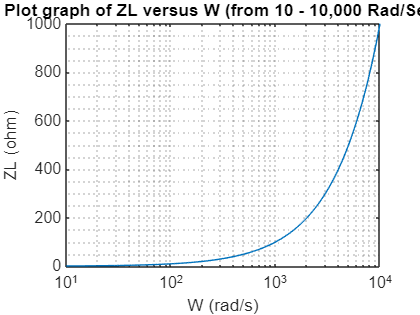

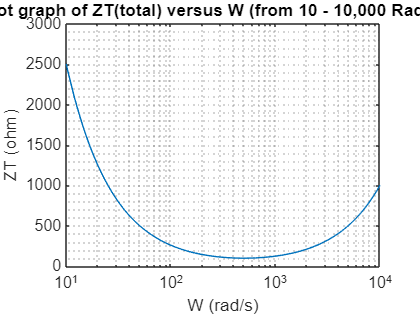

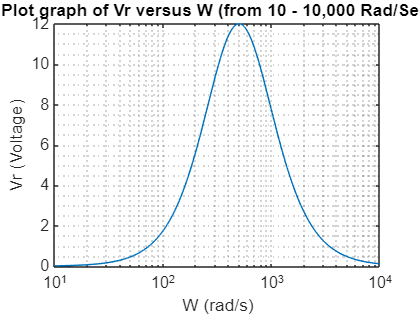

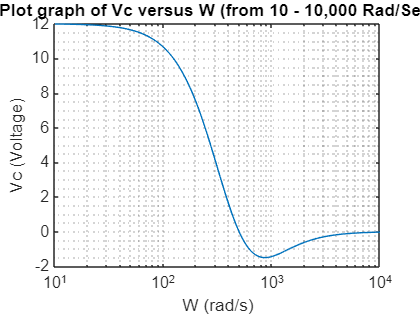

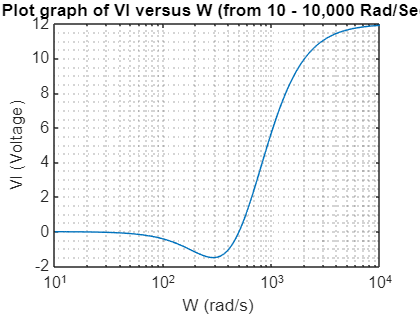

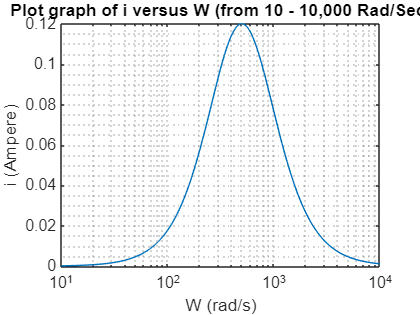

clc
clear
W = logspace(1 , 4 , 1000); % W = 10-1000 Rad/Sec
Vs = 12;                    % Voltage
R = 100;                    % Resistor
L = 100e-3;                 % Inductor
C = 40e-6;                  % Capacitor

%cal value
Zr = R;                     % ZR
Zl = 1j.*W.*L;              % ZL
Zc = -1j./(W.*C);           % ZC
Zt = Zr + Zl + Zc;          % ZT(total)
abs_Zc = abs(Zc);
abs_Zl = abs(Zl);
abs_Zt = abs(Zt);
i = Vs./Zt;
Vr = i*Zr;
Vc = i.*Zc;
Vl = i.*Zl;

data_plots = {
    struct('val', abs_Zc, 'xlabel', "W (rad/s)", 'ylabel', "ZC (ohm)", 'title', "Plot graph of ZC versus W (from 10 - 10,000 Rad/Sec)");
    struct('val', abs_Zl, 'xlabel', "W (rad/s)", 'ylabel', "ZL (ohm)", 'title', "Plot graph of ZL versus W (from 10 - 10,000 Rad/Sec)");
    struct('val', abs_Zt, 'xlabel', "W (rad/s)", 'ylabel', "ZT (ohm)", 'title', "Plot graph of ZT(total) versus W (from 10 - 10,000 Rad/Sec)");
    struct('val', real(Vr), 'xlabel', "W (rad/s)", 'ylabel', "Vr (Voltage)", 'title', "Plot graph of Vr versus W (from 10 - 10,000 Rad/Sec)");
    struct('val', real(Vc), 'xlabel', "W (rad/s)", 'ylabel', "Vc (Voltage)", 'title', "Plot graph of Vc versus W (from 10 - 10,000 Rad/Sec)");
    struct('val', real(Vl), 'xlabel', "W (rad/s)", 'ylabel', "Vl (Voltage)", 'title', "Plot graph of Vl versus W (from 10 - 10,000 Rad/Sec)");
    struct('val', real(i), 'xlabel', "W (rad/s)", 'ylabel', "i (Ampere)", 'title', "Plot graph of i versus W (from 10 - 10,000 Rad/Sec)");
};

for position = 1:length(data_plots)
    figure(position);
    semilogx(W, data_plots{position}.val);
    xlabel(data_plots{position}.xlabel);
    ylabel(data_plots{position}.ylabel);
    title(data_plots{position}.title);
    grid minor;
end


[Imax , Wmax] = max(i);
disp(['Max Current is ', num2str(abs(Imax)), ' Ampere. ','Frequency is ', num2str(W(Wmax)), ' Rad/Sec.']);

Max Current is 0.12 Ampere. Frequency is 500.8408 Rad/Sec
